# Decision Tree

load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV1=HCV;

# With original data

#  Decision Tree with original data

cdata=table2array(HCV);
x=cdata(:,1:27)

x =           56           1          35           2           1           1           1           2           2           2        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5
          46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829
          49         

y=categorical(cdata(:,29));
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.7);

%{'Gender','Fever','NauseaVomiting','Headache','Diarrhea','Fatiguegeneralizedboneache','Jaundice','Epigastricpain','HGB','BaselinehistologicalGrading'}
%"PredictorNames",{'x2','x4','x5','x6','x7','x8','x9','x10','x28'}
Decision_Tree=fitctree(Xtrain,Ytrain,'CategoricalPredictors',[2,4:10])

Decision_Tree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [2 4 5 6 7 8 9 10]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(Decision_Tree)


Decision tree for classification
  1  if x10=1 then node 2 elseif x10=2 then node 3 else 3
  2  if x21<108.5 then node 4 elseif x21>=108.5 then node 5 else 3
  3  if x27<213632 then node 6 elseif x27>=213632 then node 7 else 1
  4  if x13<12.5 then node 8 elseif x13>=12.5 then node 9 else 3
  5  if x16<46.5 then node 10 elseif x16>=46.5 then node 11 else 2
  6  if x18<107.5 then node 12 elseif x18>=107.5 then node 13 else 2
  7  if x25<111585 then node 14 elseif x25>=111585 then node 15 else 1
  8  if x2=1 then node 16 elseif x2=2 then node 17 else 3
  9  if x24<546459 then node 18 elseif x24>=546459 then node 19 else 4
 10  class = 1
 11  if x20<46.5 then node 20 elseif x20>=46.5 then node 21 else 2
 12  if x23<919149 then node 22 elseif x23>=919149 then node 23 else 2
 13  if x23<608485 then node 24 elseif x23>=608485 then node 25 else 1
 14  if x13<11.5 then node 26 elseif x13>=11.5 then node 27 else 1
 15  if x11<6493 then node 28 elseif x11>=6493 then node 29 else 4
 16  if x22<4

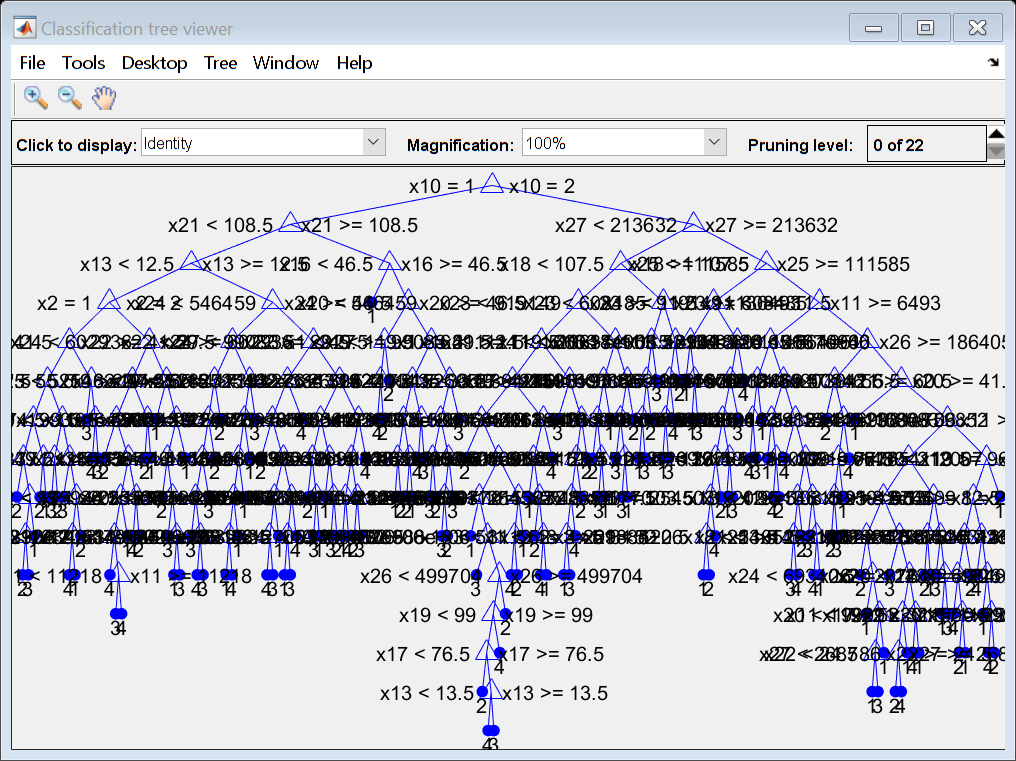

view(Decision_Tree,'mode','graph')

Ypred=predict(Decision_Tree,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

ans = 0.2692

26.92%

[E,SE,Nleaf,Best_prune_level]=cvloss(Decision_Tree,'subtrees','all')

E =     0.7709
    0.7730
    0.7709
    0.7730
    0.7730
    0.7523
    0.7523
    0.7523
    0.7513
    0.7482


SE =     0.0134
    0.0134
    0.0134
    0.0134
    0.0134
    0.0138
    0.0138
    0.0138
    0.0138
    0.0139


Nleaf =    170
   168
   130
   127
    88
    85
    80
    76
    70
    65


Best_prune_level = 22

prune_tree=prune(Decision_Tree,'Level',Best_prune_level)

prune_tree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [2 4 5 6 7 8 9 10]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(prune_tree)


Decision tree for classification
1  class = 3



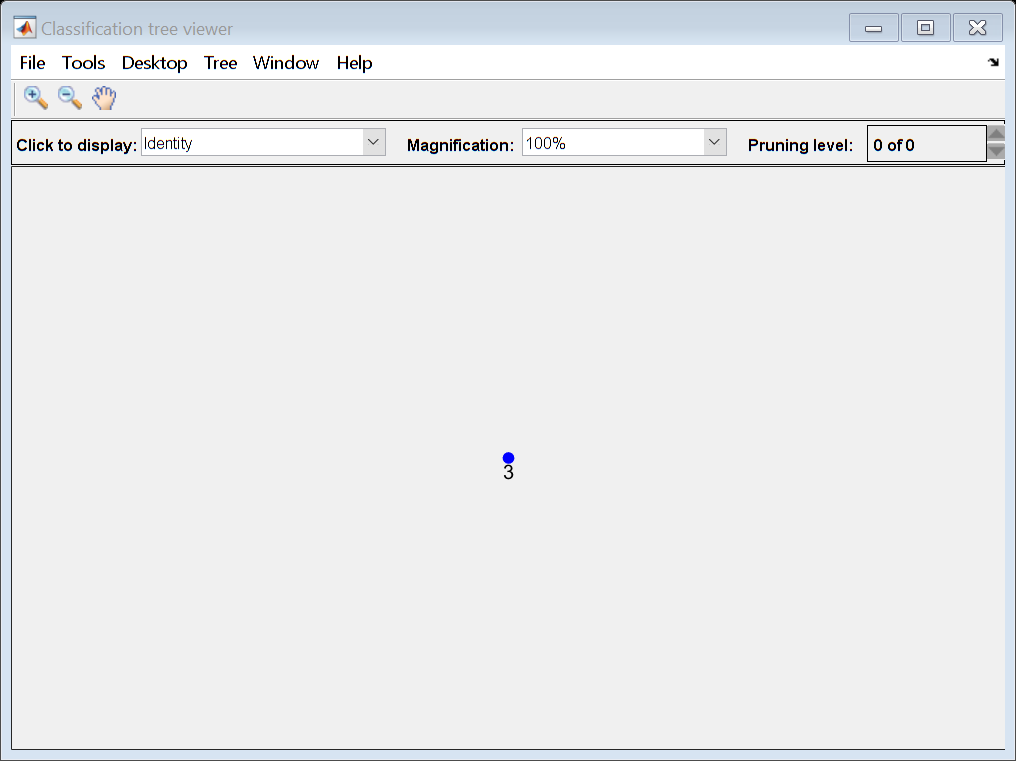

view(prune_tree,'mode','graph') % Best cross validation accuracy

Ypred=predict(prune_tree,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

ans = 0.2308

23.08%

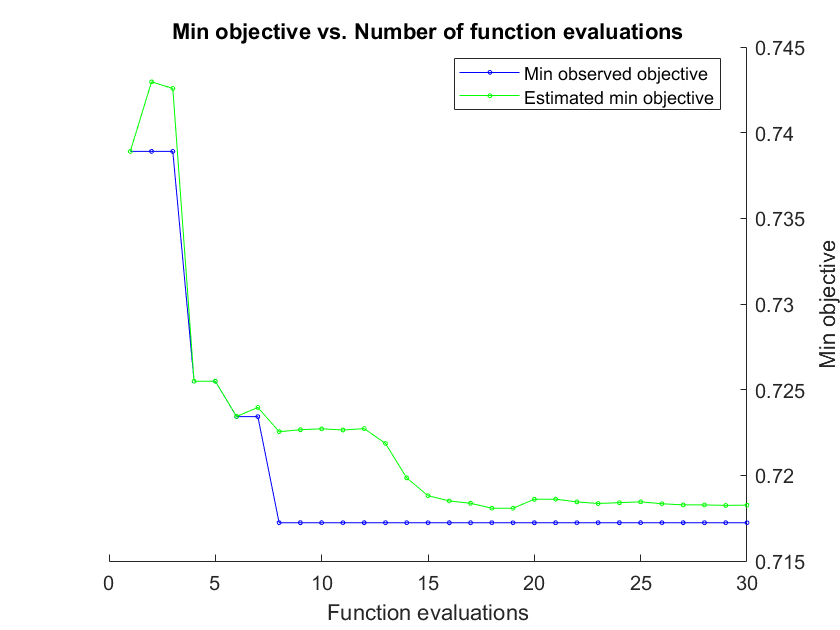

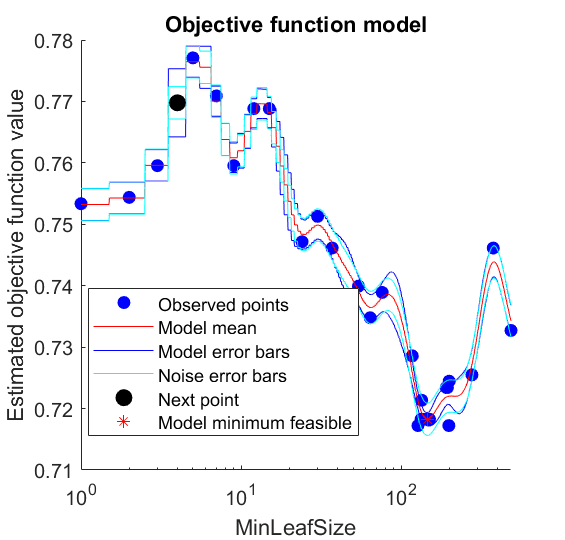

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73891 |      0.1013 |     0.73891 |     0.73891 |           76 |
|    2 | Accept |     0.76883 |     0.21789 |     0.73891 |     0.74296 |           15 |
|    3 | Accept |     0.75439 |     0.21742 |     0.73891 |     0.74258 |            2 |
|    4 | Best   |     0.72549 |     0.08258 |     0.72549 |     0.72549 |          276 |
|    5 | Accept |     0.73271 |    0.079233 |     0.72549 |      0.7255 |          484 |
|    6 | Best   |     0.72343 |     0.11124 |     0.72343 |     0.72344 |          191 |
|    7 | Accept |     0.72446 |    0.087669 |     0.72343 |     0.72396 |          199 |
|    8 | Best   |    

Mdl1 =   ClassificationTree
                         ResponseName: 'Y'
                CategoricalPredictors: [2 4 5 6 7 8 9 10]
                           ClassNames: [1    2    3    4]
                       ScoreTransform: 'none'
                      NumObservations: 969
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


Mdl1=fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto','CategoricalPredictors',[2,4:10])

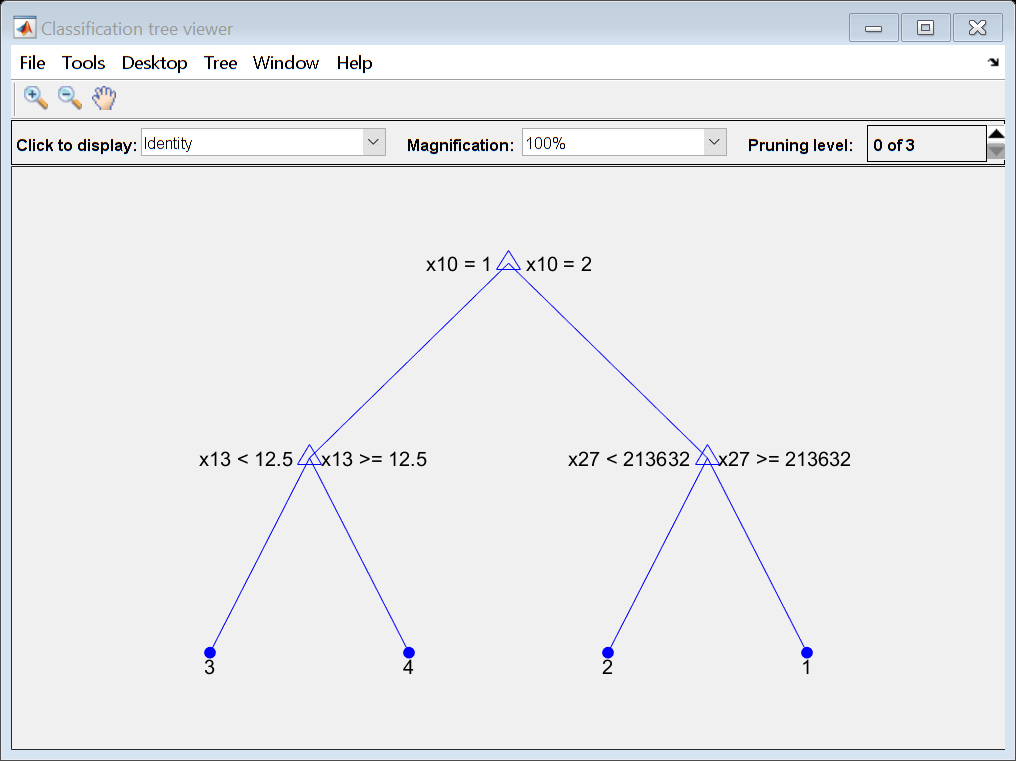

view(Mdl1,'mode','graph')

Ypred=predict(Mdl1,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

ans = 0.2476

24.76%

Bestobsmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',198,"CategoricalPredictors",[2,4:10])

Bestobsmdl =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [2 4 5 6 7 8 9 10]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(Bestobsmdl,'mode','graph')

Ypred=predict(Bestobsmdl,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

ans = 0.2476

24.76%

Bestestmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',145,"CategoricalPredictors",[2,4:10])

Bestestmdl =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [2 4 5 6 7 8 9 10]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(Bestestmdl,'mode','graph')

Ypred=predict(Bestestmdl,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

ans = 0.2476

24.76%

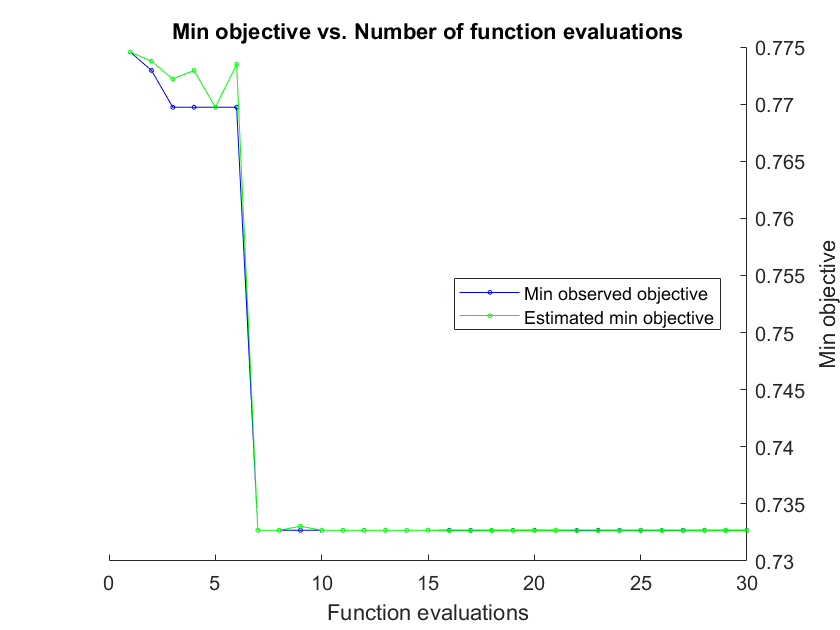

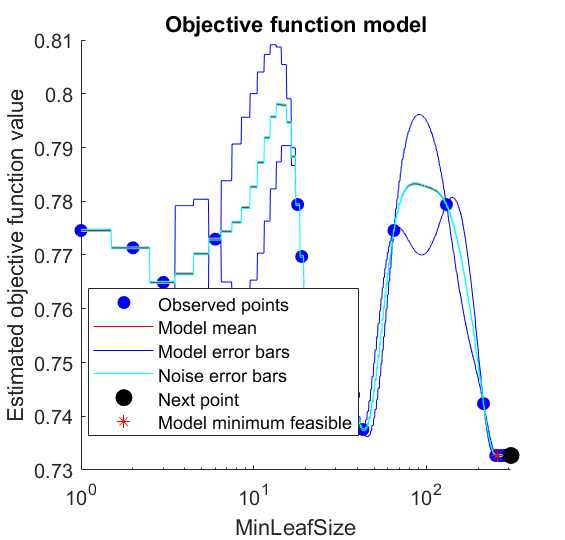

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.77456 |     0.19336 |     0.77456 |     0.77456 |            1 |
|    2 | Best   |     0.77295 |     0.22524 |     0.77295 |     0.77375 |            6 |
|    3 | Best   |     0.76973 |     0.19175 |     0.76973 |     0.77221 |           19 |
|    4 | Accept |     0.77456 |     0.17348 |     0.76973 |     0.77295 |           65 |
|    5 | Accept |     0.76973 |     0.17441 |     0.76973 |     0.76973 |           19 |
|    6 | Accept |     0.77939 |     0.18242 |     0.76973 |     0.77348 |           18 |
|    7 | Best   |     0.73269 |     0.16042 |     0.73269 |     0.73269 |          310 |
|    8 | Accept |    

ans = 0.2258

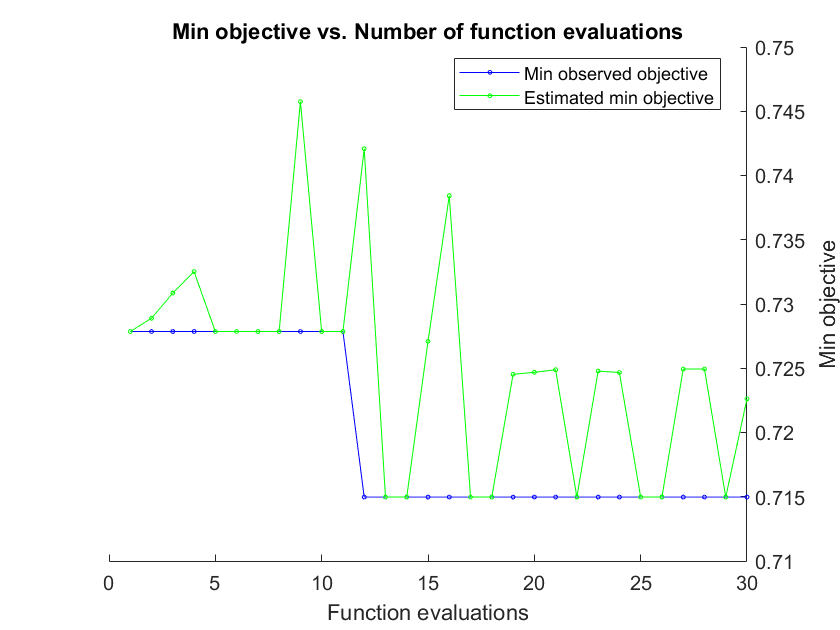

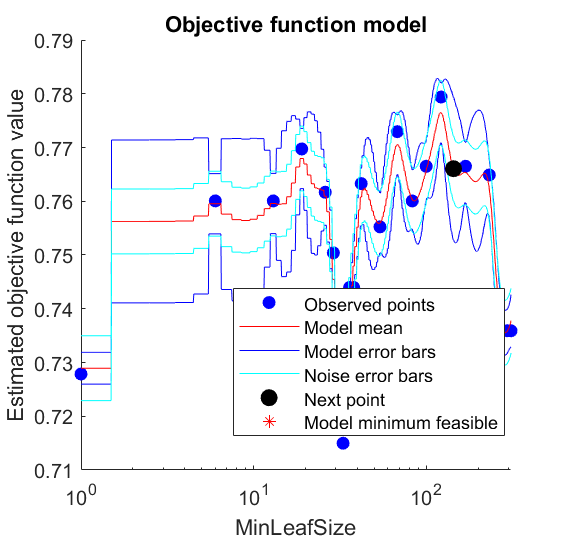

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.72786 |     0.17458 |     0.72786 |     0.72786 |            1 |
|    2 | Accept |     0.74396 |     0.22087 |     0.72786 |     0.72889 |           36 |
|    3 | Accept |     0.76006 |      0.2448 |     0.72786 |     0.73085 |            6 |
|    4 | Accept |      0.7649 |     0.18023 |     0.72786 |     0.73252 |          232 |
|    5 | Accept |     0.72786 |      0.2406 |     0.72786 |     0.72786 |            1 |
|    6 | Accept |     0.72947 |     0.17481 |     0.72786 |     0.72786 |           30 |
|    7 | Accept |     0.76167 |      0.1724 |     0.72786 |     0.72786 |           26 |
|    8 | Accept |    

ans = 0.2581

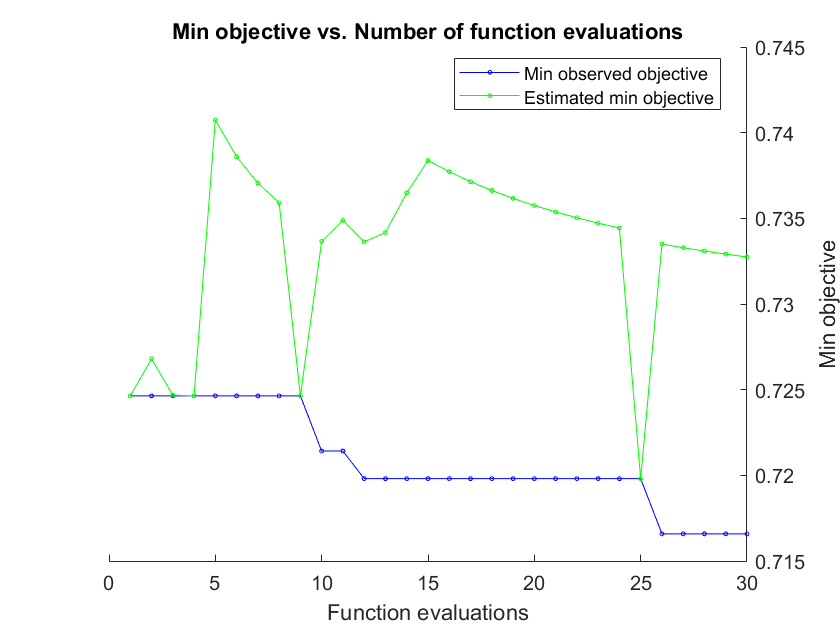

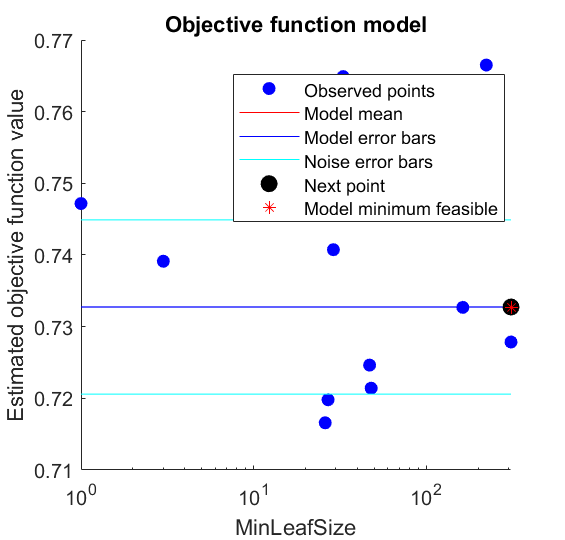

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.72464 |     0.12093 |     0.72464 |     0.72464 |           47 |
|    2 | Accept |     0.73269 |      0.1242 |     0.72464 |      0.7268 |          163 |
|    3 | Accept |      0.7504 |     0.21096 |     0.72464 |     0.72468 |           10 |
|    4 | Accept |     0.73913 |     0.26442 |     0.72464 |     0.72464 |            3 |
|    5 | Accept |     0.75684 |     0.17565 |     0.72464 |     0.74074 |           64 |
|    6 | Accept |     0.72786 |     0.15208 |     0.72464 |     0.73859 |          310 |
|    7 | Accept |     0.72786 |     0.14846 |     0.72464 |     0.73706 |          310 |
|    8 | Accept |    

ans = 0.2194

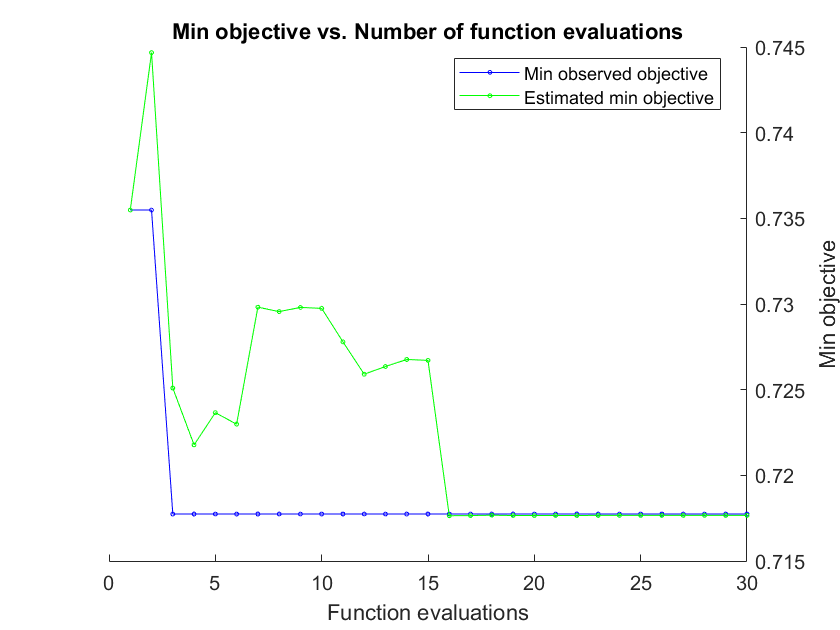

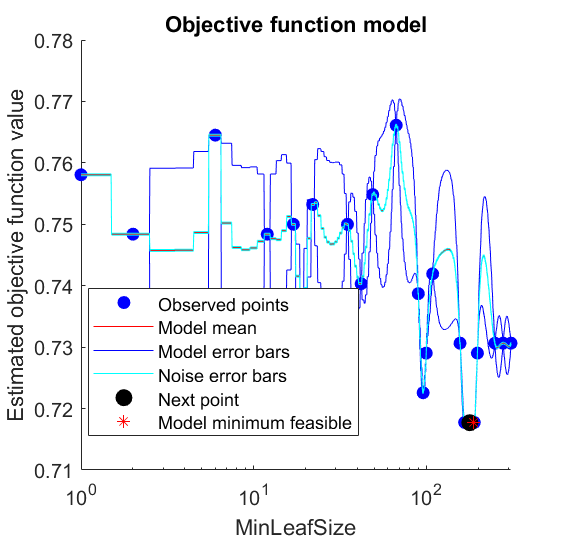

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73548 |    0.088206 |     0.73548 |     0.73548 |           19 |
|    2 | Accept |     0.76452 |     0.20748 |     0.73548 |     0.74467 |            6 |
|    3 | Best   |     0.71774 |     0.16716 |     0.71774 |      0.7251 |          187 |
|    4 | Accept |     0.75806 |     0.27047 |     0.71774 |     0.72178 |            1 |
|    5 | Accept |     0.73065 |     0.14584 |     0.71774 |     0.72366 |          310 |
|    6 | Accept |     0.72258 |      0.1787 |     0.71774 |     0.72299 |           96 |
|    7 | Accept |     0.74194 |     0.18076 |     0.71774 |     0.72982 |          109 |
|    8 | Accept |    

ans = 0.2436

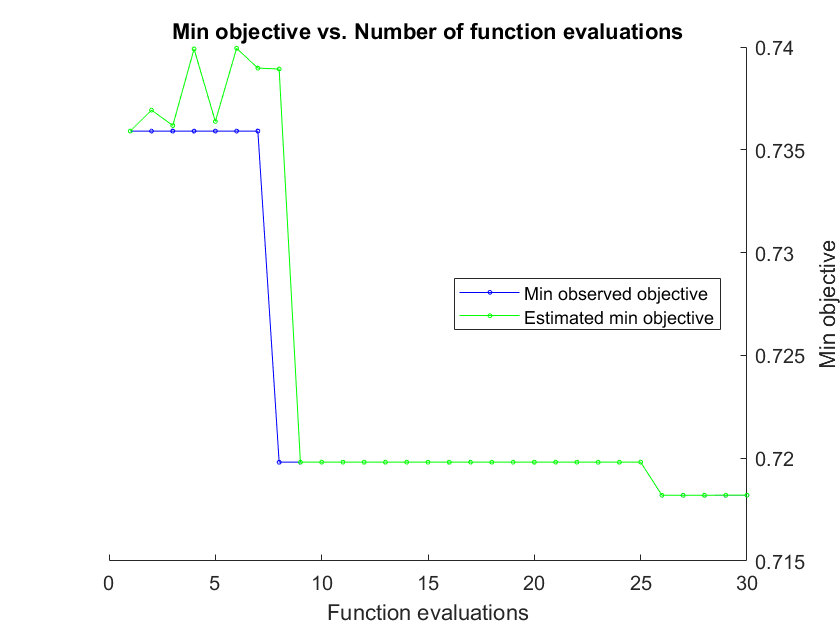

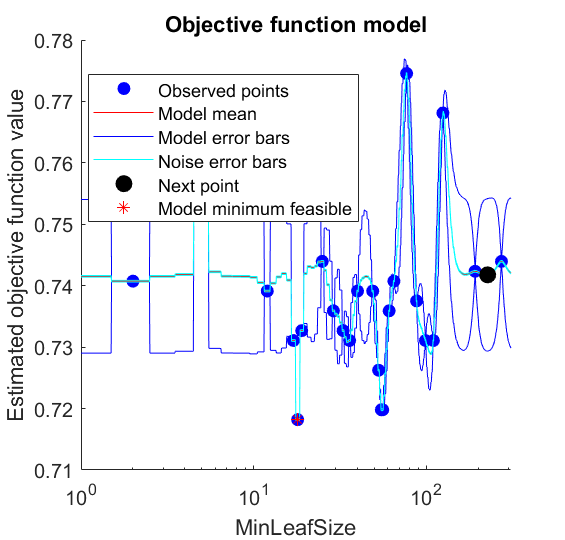

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73591 |     0.12821 |     0.73591 |     0.73591 |           61 |
|    2 | Accept |     0.74074 |     0.27088 |     0.73591 |     0.73693 |            2 |
|    3 | Accept |     0.73913 |     0.22666 |     0.73591 |     0.73618 |           12 |
|    4 | Accept |     0.74396 |      0.1901 |     0.73591 |     0.73991 |          273 |
|    5 | Accept |     0.73913 |     0.15132 |     0.73591 |     0.73638 |           49 |
|    6 | Accept |     0.74074 |     0.18244 |     0.73591 |     0.73994 |           65 |
|    7 | Accept |     0.75201 |     0.23878 |     0.73591 |     0.73897 |            5 |
|    8 | Best   |    

ans = 0.2194

fold=5;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy5_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x(train,:);
    Xtest=x(test,:);
    Ytrain=y(train,:);
    Ytest=y(test,:);
    
    %Decision tree
    Mdl1=fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto','CategoricalPredictors',[2,4:10]);
    Ypred=predict(Mdl1,Xtest); 
    sum(Ypred==Ytest)/length(Ytest)
   
    % For model accuracy
    accuracy5_(i)=sum(Ypred==Ytest)/length(Ytest);
end

accuracy5_

accuracy5_ =     0.2258    0.2581    0.2194    0.2436    0.2194


avg_accuracy_5=mean(accuracy5_)

avg_accuracy_5 = 0.2332

23.32%

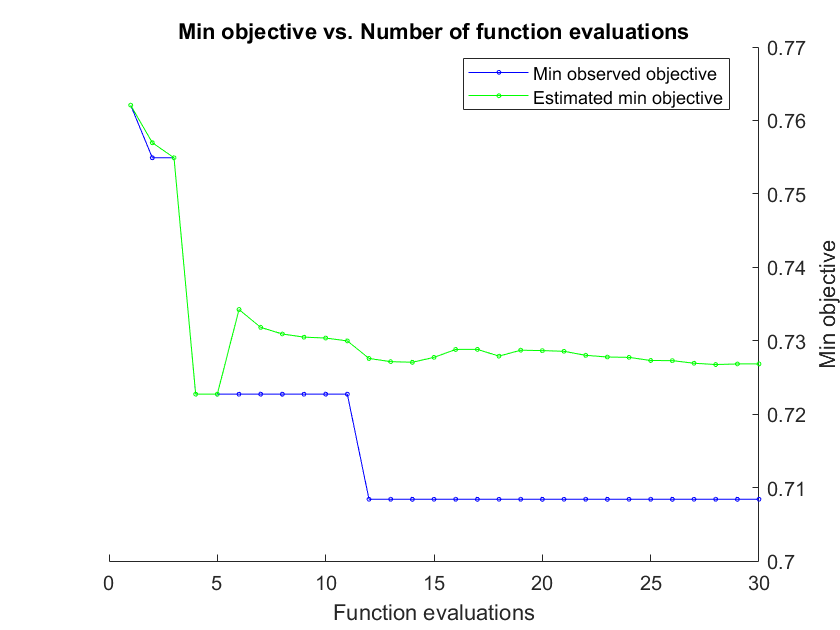

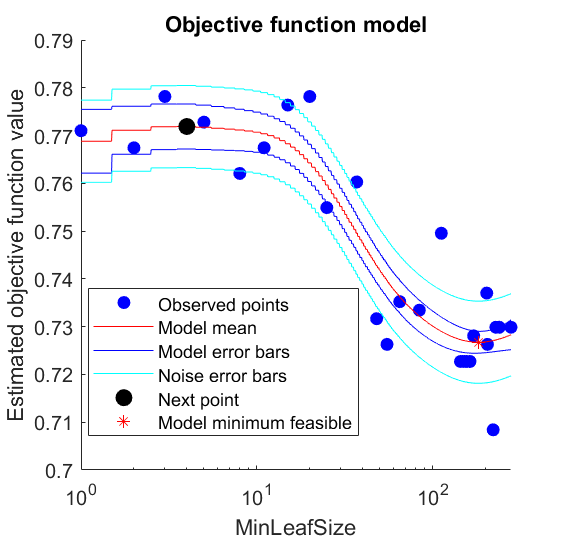

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.76208 |     0.19292 |     0.76208 |     0.76208 |            8 |
|    2 | Best   |     0.75492 |     0.17942 |     0.75492 |     0.75696 |           25 |
|    3 | Accept |     0.77102 |     0.23715 |     0.75492 |     0.75492 |            1 |
|    4 | Best   |     0.72272 |     0.14324 |     0.72272 |     0.72272 |          153 |
|    5 | Accept |     0.72987 |     0.15321 |     0.72272 |     0.72273 |          279 |
|    6 | Accept |     0.74955 |     0.17503 |     0.72272 |     0.73425 |          112 |
|    7 | Accept |     0.72987 |     0.17224 |     0.72272 |     0.73182 |          279 |
|    8 | Accept |    

ans = 0.1774

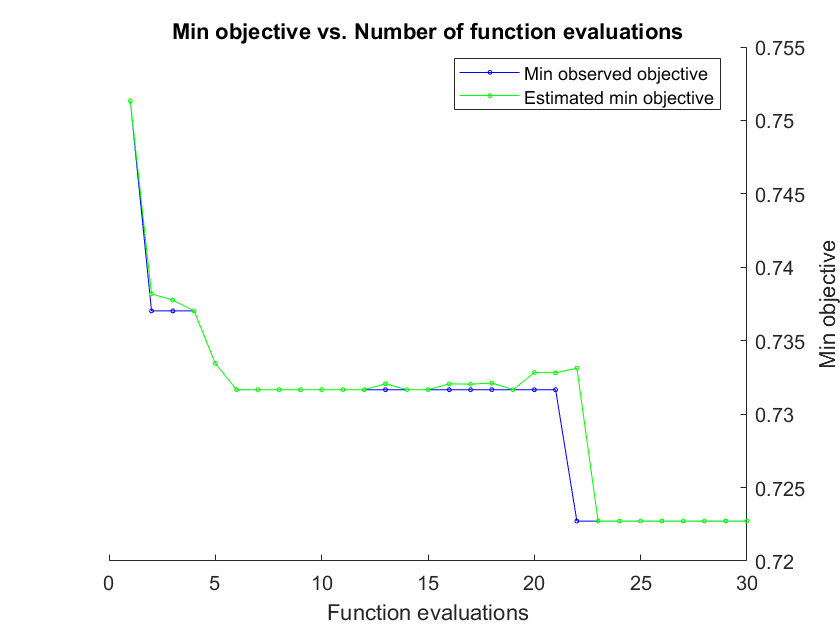

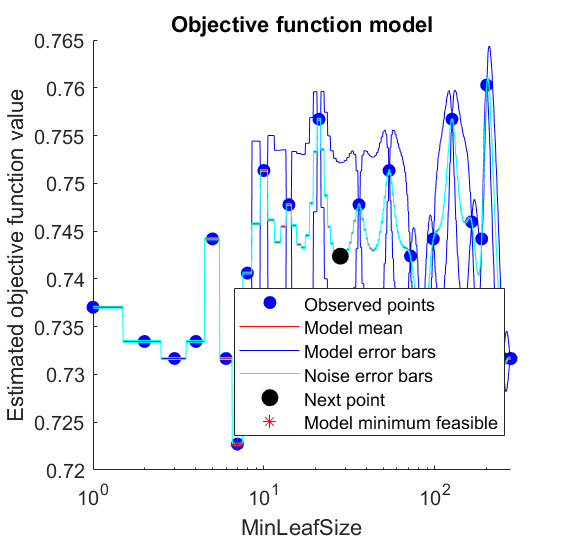

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.75134 |     0.15441 |     0.75134 |     0.75134 |           10 |
|    2 | Best   |     0.73703 |     0.26604 |     0.73703 |     0.73819 |            1 |
|    3 | Accept |     0.74419 |     0.16015 |     0.73703 |     0.73777 |          188 |
|    4 | Accept |     0.74776 |      0.1706 |     0.73703 |     0.73703 |           36 |
|    5 | Best   |     0.73345 |     0.23599 |     0.73345 |     0.73345 |            2 |
|    6 | Best   |     0.73166 |     0.26518 |     0.73166 |     0.73167 |            3 |
|    7 | Accept |     0.73345 |     0.21633 |     0.73166 |     0.73166 |            4 |
|    8 | Accept |    

ans = 0.2419

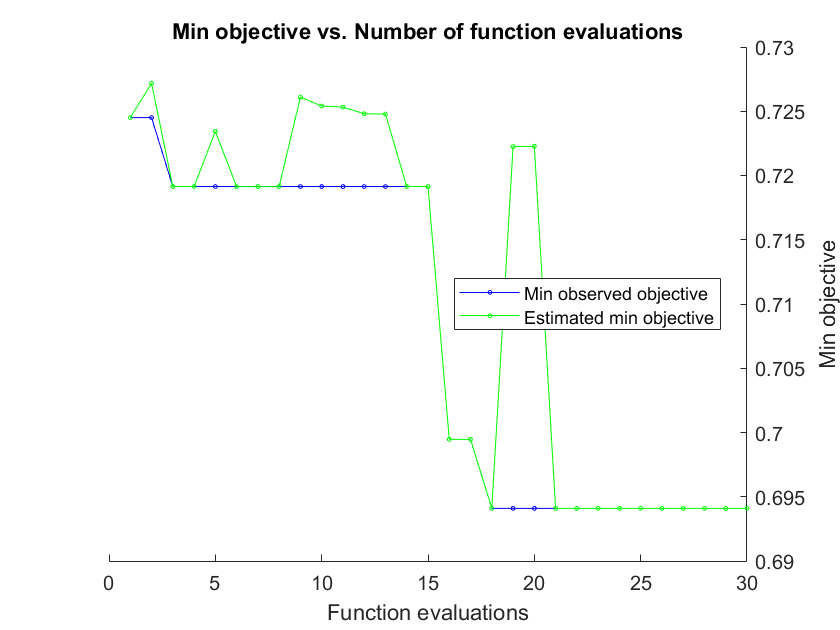

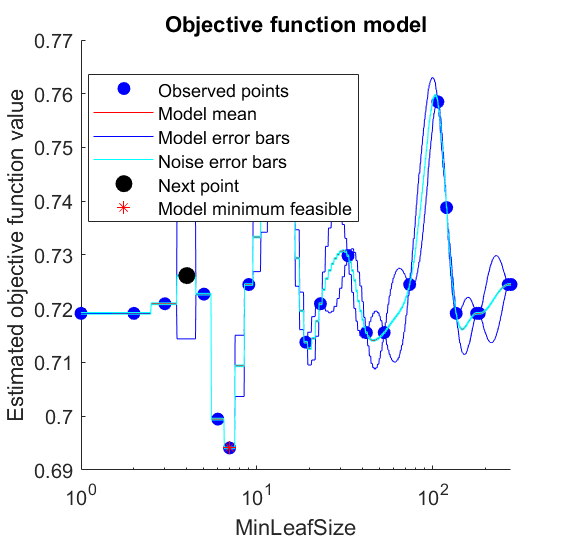

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.72451 |     0.15256 |     0.72451 |     0.72451 |            9 |
|    2 | Accept |     0.72987 |      0.1589 |     0.72451 |     0.72718 |           33 |
|    3 | Best   |     0.71914 |     0.21215 |     0.71914 |     0.71914 |            1 |
|    4 | Accept |     0.71914 |     0.17122 |     0.71914 |     0.71914 |          184 |
|    5 | Accept |     0.72451 |     0.16198 |     0.71914 |     0.72343 |          269 |
|    6 | Accept |     0.71914 |      0.1614 |     0.71914 |     0.71914 |          178 |
|    7 | Accept |     0.71914 |     0.21312 |     0.71914 |     0.71914 |            2 |
|    8 | Accept |    

ans = 0.2419

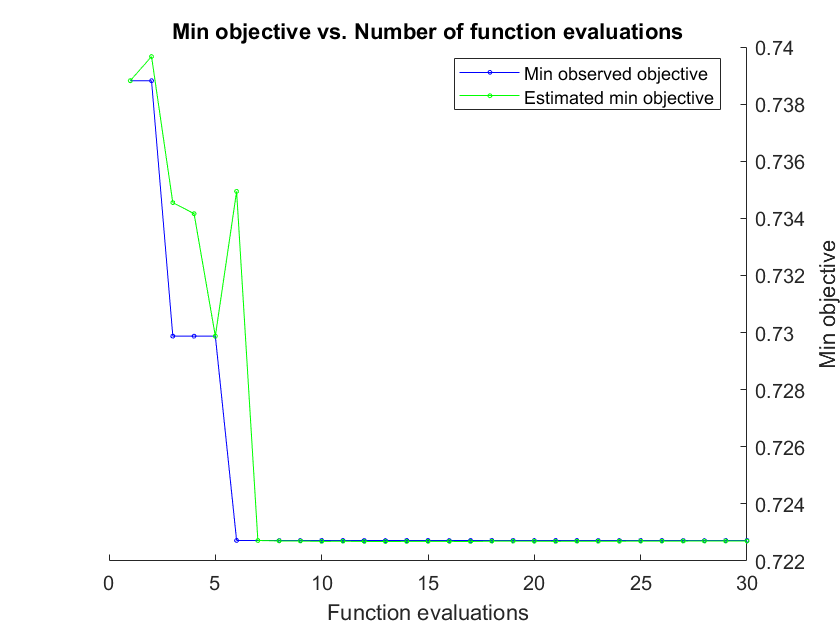

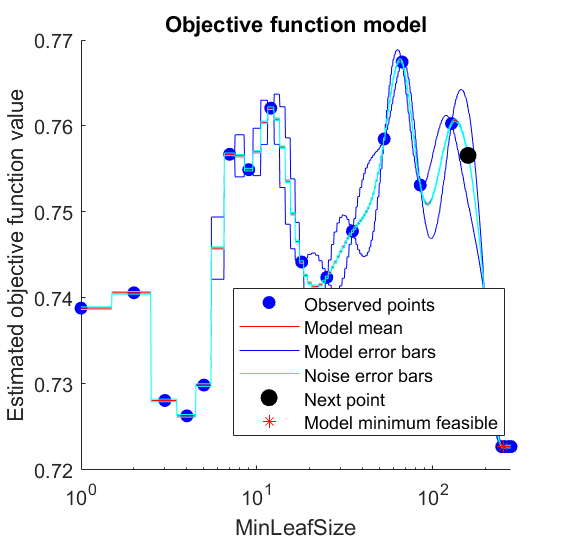

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73882 |     0.12115 |     0.73882 |     0.73882 |          200 |
|    2 | Accept |     0.74061 |     0.19536 |     0.73882 |     0.73967 |            2 |
|    3 | Best   |     0.72987 |     0.22151 |     0.72987 |     0.73455 |            5 |
|    4 | Accept |     0.74776 |     0.16612 |     0.72987 |     0.73416 |           35 |
|    5 | Accept |     0.72987 |     0.23054 |     0.72987 |     0.72988 |            5 |
|    6 | Best   |     0.72272 |     0.12735 |     0.72272 |     0.73494 |          247 |
|    7 | Accept |     0.72272 |     0.12446 |     0.72272 |     0.72272 |          268 |
|    8 | Accept |    

ans = 0.1613

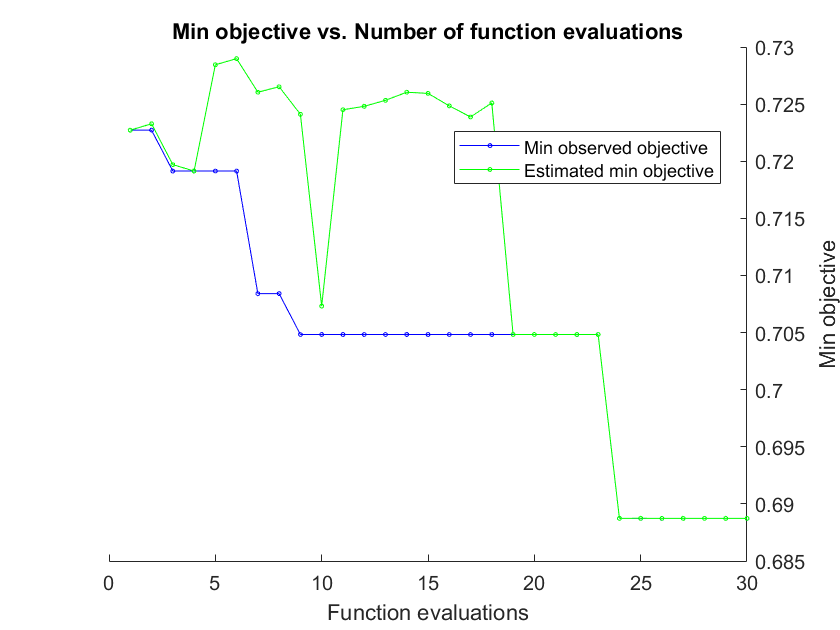

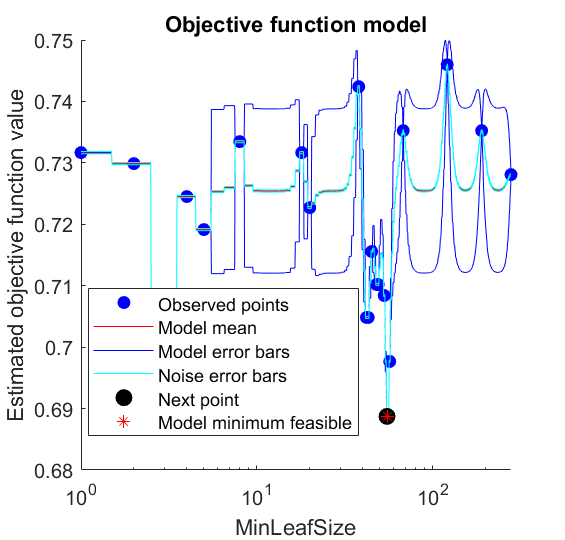

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.72272 |     0.23035 |     0.72272 |     0.72272 |           20 |
|    2 | Accept |     0.73166 |      0.2431 |     0.72272 |     0.72328 |            1 |
|    3 | Best   |     0.71914 |     0.24281 |     0.71914 |      0.7197 |            5 |
|    4 | Accept |     0.73524 |     0.17655 |     0.71914 |     0.71914 |          190 |
|    5 | Accept |     0.73345 |     0.24042 |     0.71914 |     0.72844 |            8 |
|    6 | Accept |     0.73166 |     0.18133 |     0.71914 |     0.72898 |           18 |
|    7 | Best   |     0.70841 |     0.23831 |     0.70841 |     0.72604 |            3 |
|    8 | Accept |    

ans = 0.1935

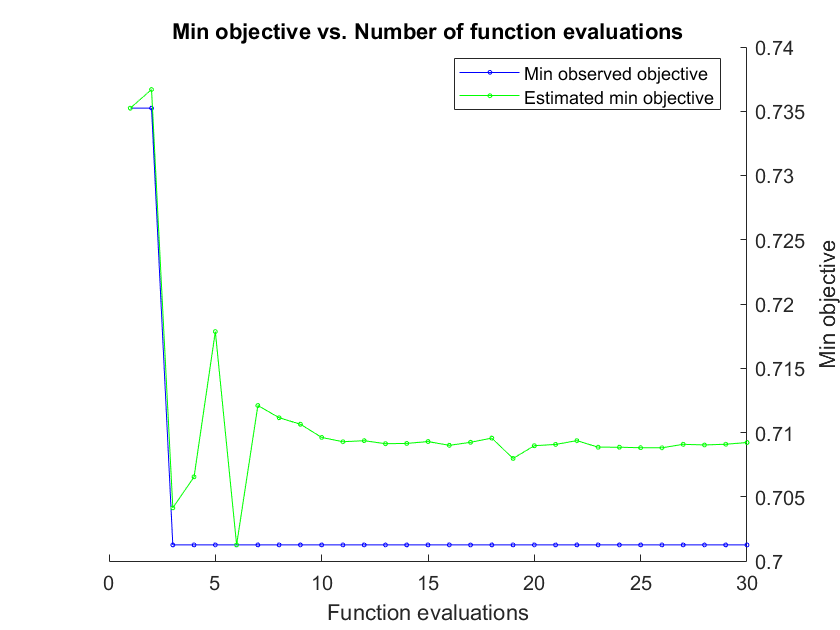

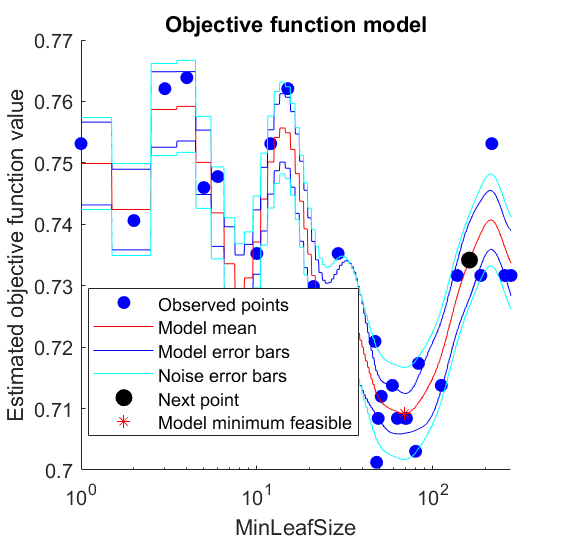

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73524 |     0.14903 |     0.73524 |     0.73524 |           10 |
|    2 | Accept |     0.75313 |     0.20499 |     0.73524 |     0.73669 |            1 |
|    3 | Best   |     0.70125 |     0.16073 |     0.70125 |     0.70414 |           48 |
|    4 | Accept |     0.73166 |      0.1381 |     0.70125 |     0.70655 |          257 |
|    5 | Accept |     0.72093 |     0.18344 |     0.70125 |     0.71786 |           47 |
|    6 | Accept |     0.70841 |     0.23083 |     0.70125 |     0.70126 |           49 |
|    7 | Accept |     0.71199 |     0.20089 |     0.70125 |      0.7121 |           51 |
|    8 | Accept |    

ans = 0.2581

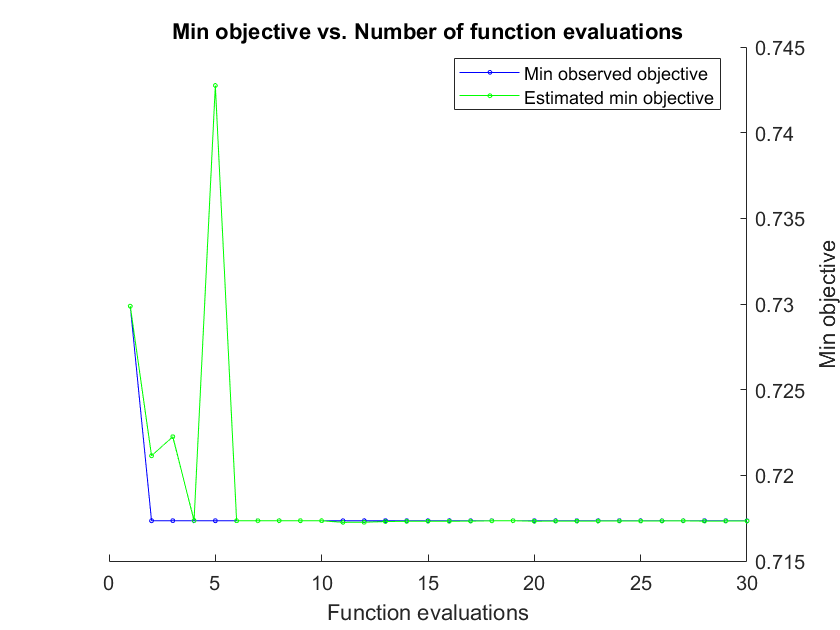

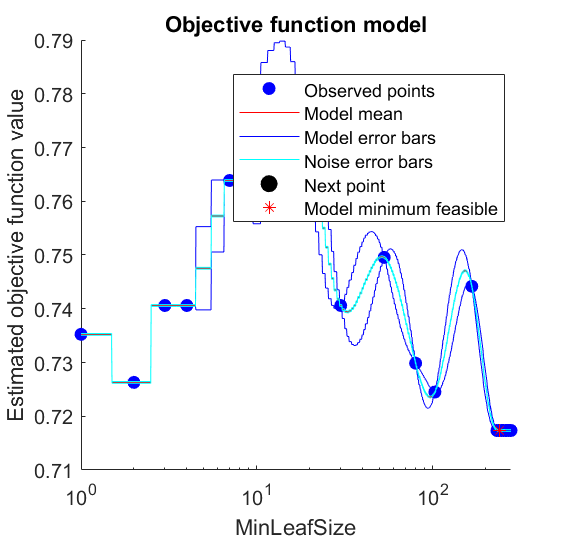

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.72987 |     0.15734 |     0.72987 |     0.72987 |           80 |
|    2 | Best   |     0.71735 |     0.14475 |     0.71735 |     0.72115 |          254 |
|    3 | Accept |     0.74061 |     0.21279 |     0.71735 |     0.72225 |            4 |
|    4 | Accept |     0.78175 |     0.17517 |     0.71735 |     0.71736 |           17 |
|    5 | Accept |     0.74419 |     0.14179 |     0.71735 |     0.74275 |          167 |
|    6 | Accept |     0.71735 |     0.15883 |     0.71735 |     0.71735 |          279 |
|    7 | Accept |     0.74955 |     0.14186 |     0.71735 |     0.71735 |           53 |
|    8 | Accept |    

ans = 0.3065

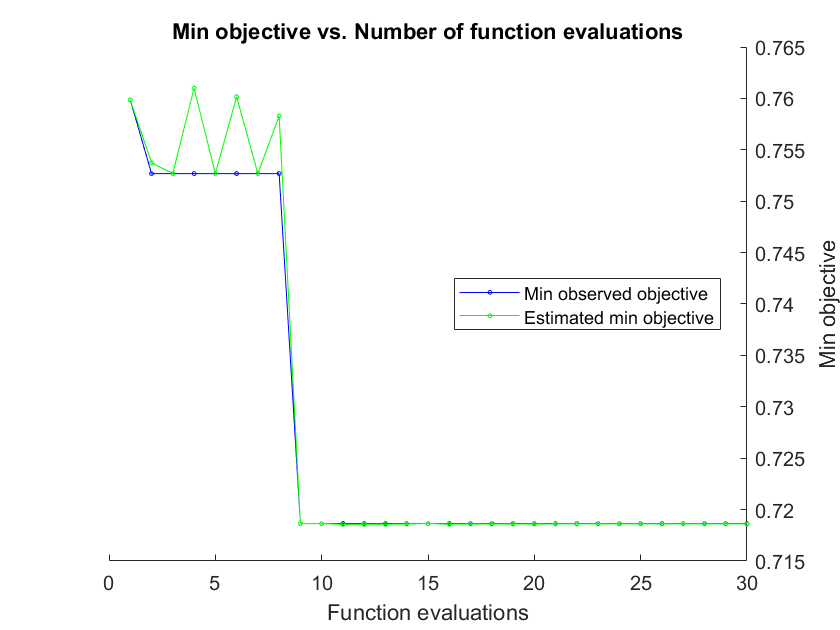

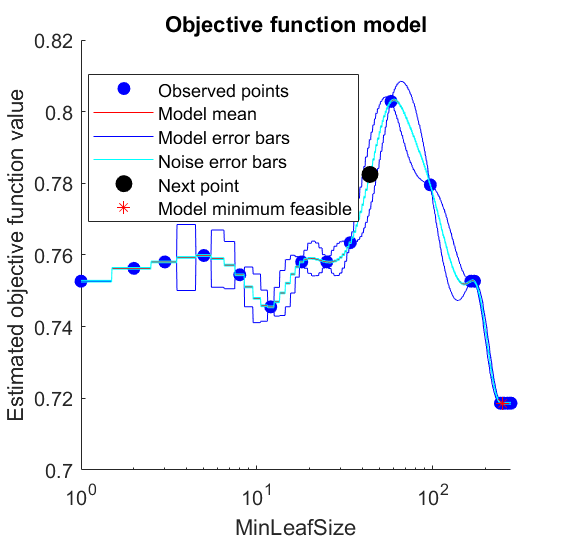

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.75986 |     0.19154 |     0.75986 |     0.75986 |            5 |
|    2 | Best   |     0.75269 |     0.18584 |     0.75269 |     0.75374 |            1 |
|    3 | Accept |     0.77957 |     0.15944 |     0.75269 |     0.75269 |           97 |
|    4 | Accept |     0.76344 |     0.25445 |     0.75269 |       0.761 |           34 |
|    5 | Accept |     0.75269 |     0.28289 |     0.75269 |     0.75269 |            1 |
|    6 | Accept |     0.75269 |     0.19282 |     0.75269 |     0.76016 |          165 |
|    7 | Accept |     0.75269 |     0.25076 |     0.75269 |     0.75269 |            1 |
|    8 | Accept |    

ans = 0.2063

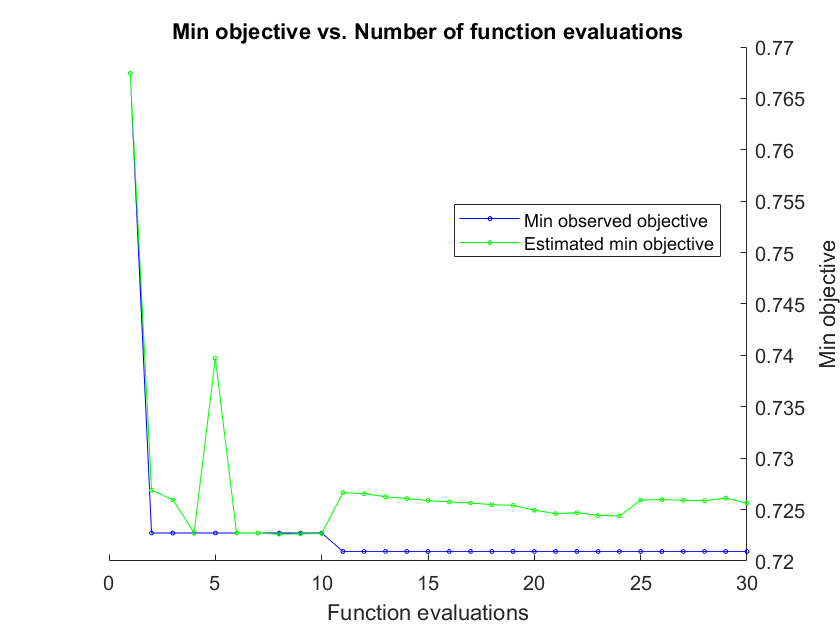

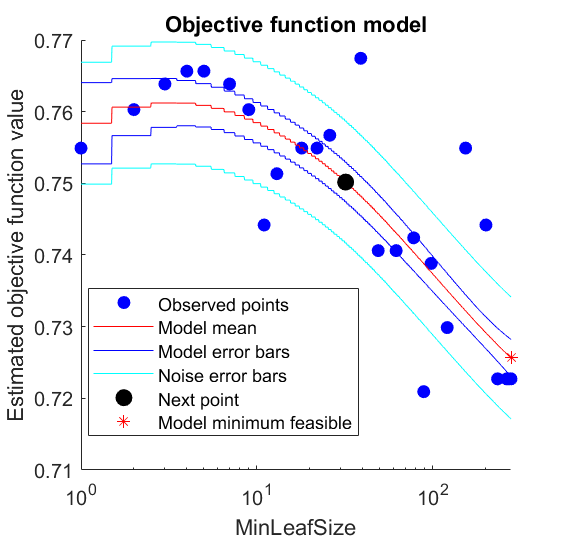

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.76744 |     0.12303 |     0.76744 |     0.76744 |           39 |
|    2 | Best   |     0.72272 |     0.11824 |     0.72272 |     0.72689 |          264 |
|    3 | Accept |     0.75492 |     0.28393 |     0.72272 |     0.72596 |            1 |
|    4 | Accept |     0.76029 |     0.20846 |     0.72272 |     0.72274 |            9 |
|    5 | Accept |     0.74419 |      0.1674 |     0.72272 |     0.73973 |          201 |
|    6 | Accept |     0.72272 |     0.19476 |     0.72272 |     0.72272 |          279 |
|    7 | Accept |     0.76386 |     0.27985 |     0.72272 |     0.72272 |            3 |
|    8 | Accept |    

ans = 0.2581

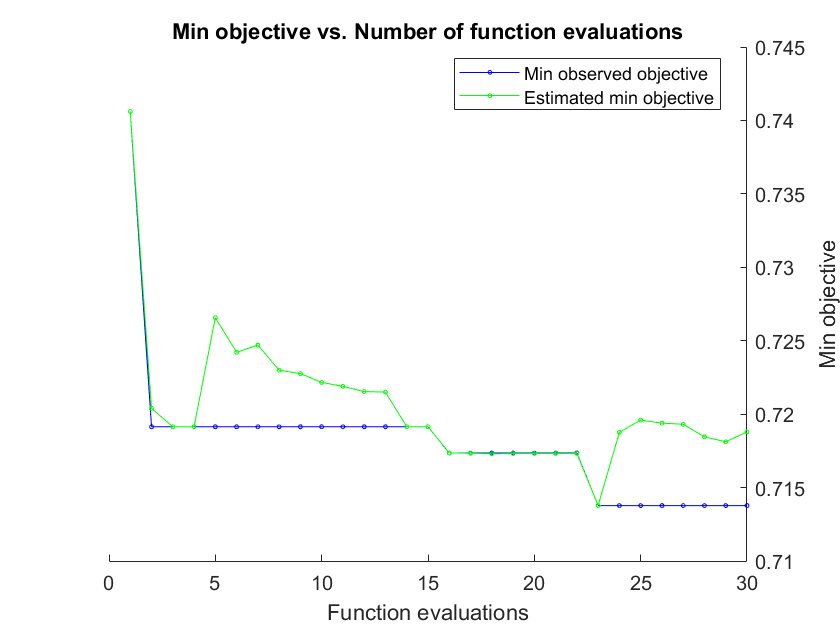

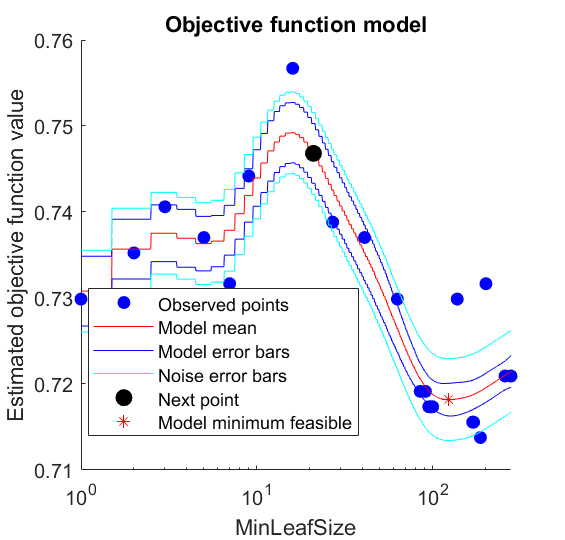

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.74061 |      0.1875 |     0.74061 |     0.74061 |            3 |
|    2 | Best   |     0.71914 |     0.18665 |     0.71914 |      0.7204 |           85 |
|    3 | Accept |     0.72093 |     0.13518 |     0.71914 |     0.71914 |          258 |
|    4 | Accept |     0.72987 |     0.24073 |     0.71914 |     0.71914 |            1 |
|    5 | Accept |     0.72987 |     0.13619 |     0.71914 |     0.72657 |          138 |
|    6 | Accept |     0.72093 |     0.13605 |     0.71914 |     0.72421 |          279 |
|    7 | Accept |     0.73882 |     0.19035 |     0.71914 |      0.7247 |           27 |
|    8 | Accept |    

ans = 0.2097

fold=10;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy10_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x(train,:);
    Xtest=x(test,:);
    Ytrain=y(train,:);
    Ytest=y(test,:);
    
    %Decision tree
    Mdl1=fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto','CategoricalPredictors',[2,4:10]);
    Ypred=predict(Mdl1,Xtest); 
    sum(Ypred==Ytest)/length(Ytest)
   
    % For model accuracy
    accuracy10_(i)=sum(Ypred==Ytest)/length(Ytest);
end

accuracy10_

accuracy10_ =     0.1774    0.2419    0.2419    0.1613    0.1935    0.2581    0.3065    0.2063    0.2581    0.2097


avg_accuracy_10=mean(accuracy10_)

avg_accuracy_10 = 0.2255

22.55%

# K-means clustering

The standard k-means algorithm isn't directly applicable to categorical data

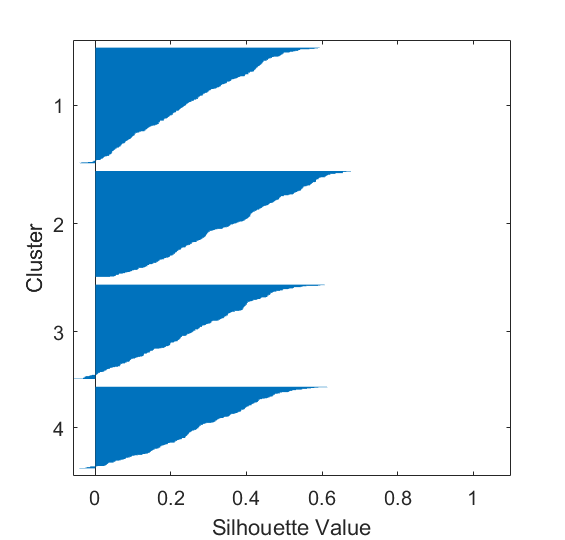

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.7);
idx=kmeans(Xtrain,4);
silhouette(Xtrain,idx)

% Scaling data from [1,2]
resdata=cdata;
for i=[1,3,11:27]
    res=rescale(cdata(:,i),1,2);
    resdata(:,i)=res;
end
cdata

cdata =           56           1          35           2           1           1           1           2           2           2        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5          13           2
          46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346      

resdata

resdata =     1.8276    1.0000    2.0000    2.0000    1.0000    1.0000    1.0000    2.0000    2.0000    2.0000    1.4867    1.3597    1.8000    1.1433    1.6742    1.5056    1.1461    1.7865    1.4719    1.0000    1.0000    1.0000    1.5456    1.5280    1.0772    1.0000    1.0000   13.0000    2.0000
    1.4828    1.0000    1.5385    1.0000    2.0000    2.0000    1.0000    2.0000    2.0000    1.0000    2.0000    1.5100    1.0000    1.2724    1.5843    1.9438    1.6292    1.4045    1.8315    1.4228    1.9593    1.9750    1.0338    1.4482    1.1707    1.4166    1.0384    4.0000    2.0000
    1.8621    1.0000    1.8462    2.0000    2.0000    2.0000    2.0000    1.0000    1.0000    1.0000    1.1303    1.6695    1.4000    1.4384    1.8315    1.1124    1.6292    1.7640    1.8652    1.0000    1.0000    1.0000    1.4755    1.5503    1.0000    1.9103    1.6896    4.0000    4.0000
    1.5862    2.0000    1.8462    1.0000    2.0000    1.0000    2.0000    1.0000    2.0000    1.0000    1.3841    1.8

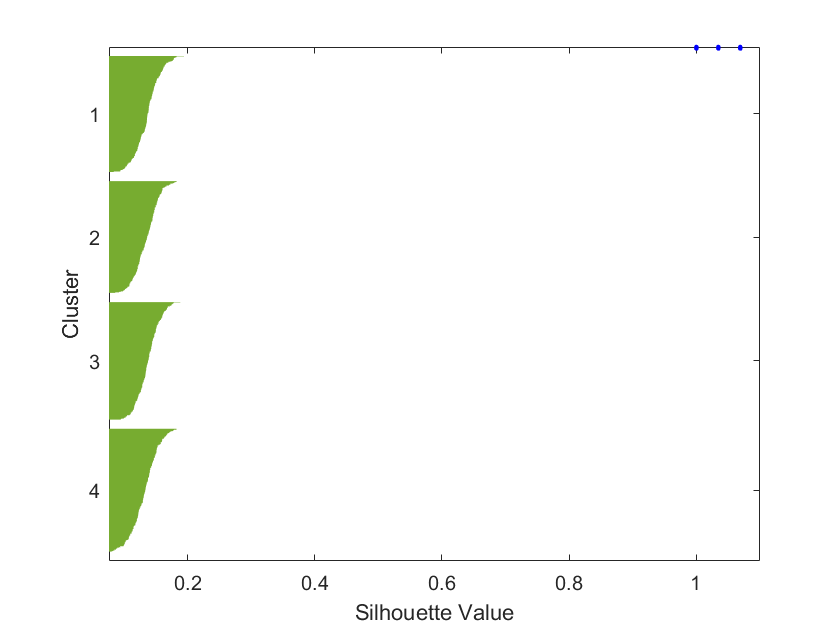

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(resdata(:,1:27),resdata(:,29),0.7);
idx=kmeans(Xtrain,4);
silhouette(Xtrain,idx)

opts = statset('Display','iter');
[idx,C,sumd,d,midx,info] = kmedoids(resdata(:,[11,12]),4,'Distance','cityblock','Options',opts);

   rep	    iter	         sum
     1	       1	     349.906
     1	       2	     343.463
     1	       3	     342.926
     1	       4	     342.184
     1	       5	     342.168
     1	       6	     342.168
Best total sum of distances = 342.168


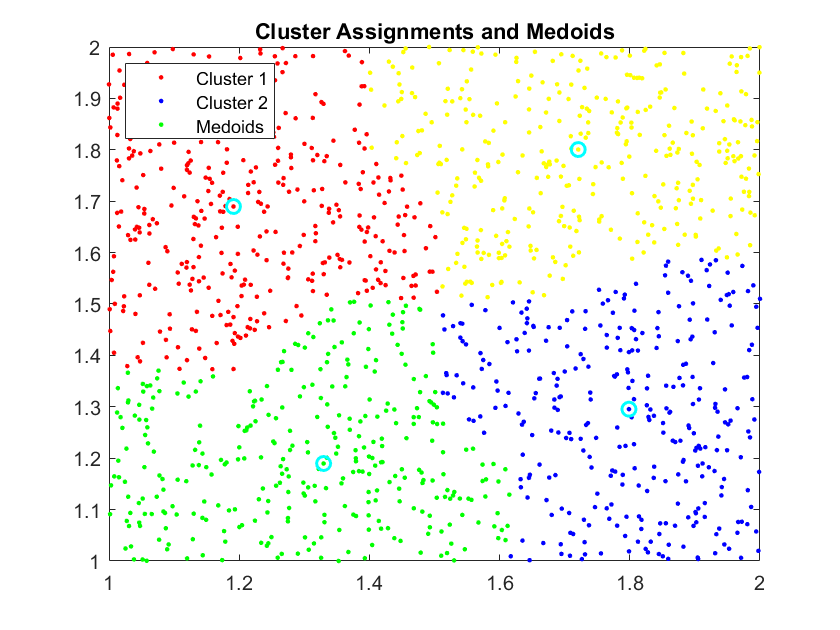

figure;
plot(resdata(idx==1,11),resdata(idx==1,12),'r.','MarkerSize',7)
hold on
plot(resdata(idx==2,11),resdata(idx==2,12),'b.','MarkerSize',7)
hold on
plot(resdata(idx==3,11),resdata(idx==3,12),'g.','MarkerSize',7)
hold on
plot(resdata(idx==4,11),resdata(idx==4,12),'y.','MarkerSize',7)
plot(C(:,1),C(:,2),'co',...
     'MarkerSize',7,'LineWidth',1.5)
legend('Cluster 1','Cluster 2','Cluster 3','Cluster 4',...
       'Location','NW');
title('Cluster Assignments and Medoids');
hold off

idx

idx =      4
     4
     1
     3
     2
     1
     1
     3
     4
     4


resdata(:,29)

ans =      2
     2
     4
     3
     1
     4
     4
     3
     2
     2


% Pearson's coefficient remains same
outrel=zeros(27,2);
for i=1:27
    feax=resdata(:,i);
    gr=resdata(:,28);
    st=resdata(:,29);
    outrel(i,1)=corr(feax,gr);
    outrel(i,2)=corr(feax,gr);
end
t=array2table(outrel,'RowNames',HCV.Properties.VariableNames(1:27),'VariableNames',{'Grade corr','Stage corr'})

t = 27×2 table
                                  Grade corr    Stage corr
                                  __________    __________

    Age                            -0.040705     -0.040705
    Gender                          0.014559      0.014559
    BMI                            -0.023045     -0.023045
    Fever                          -0.031563     -0.031563
    NauseaVomting                  -0.056782     -0.056782
    Headache                       -0.011241     -0.011241
    Diarrhea                        0.031891      0.031891
    Fatiguegeneralizedboneache     -0.022027     -0.022027
    Jaundice                      -0.0077696    -0.0077696
    Epigastricpain                -0.0056327    -0.0056327
    WBC                       

ans = 9

# KNN

# With discretized data

for j=1:1385
    
    %Age
    if HCV.Age(j)<32
    HCV1.Age(j)=1;
    else
        if HCV.Age(j)<37
            HCV1.Age(j)=2;
        else 
            if HCV.Age(j)<42
                HCV1.Age(j)=3;
            else
                if HCV.Age(j)<47
                    HCV1.Age(j)=4;
                else
                    if HCV.Age(j)<52
                        HCV1.Age(j)=5;
                    else 
                        if HCV.Age(j)<57
                            HCV1.Age(j)=6;
                        else 
                            if HCV.Age(j)<62
                                HCV1.Age(j)=7;
                            end
                        end
                    end
                end
            end
        end
    end
    
    %BMI
    if HCV1.BMI(j)<18.5
        HCV1.BMI(j)=1;
    else
        if HCV1.BMI(j)<25
            HCV1.BMI(j)=2;
        else
            if HCV1.BMI(j)<30
                HCV1.BMI(j)=3;
            else
                if HCV1.BMI(j)<35
                    HCV1.BMI(j)=4;
                else
                    if HCV1.BMI(j)<40
                        HCV1.BMI(j)=5;
                    end 
                end
            end
        end 
    end
    
    % WBC
    if HCV.WBC(j)<4000
        HCV1.WBC(j)=1;
    else
        if HCV.WBC(j)<11000
            HCV1.WBC(j)=2;
        else
            HCV1.WBC(j)=3;
        end
    end
    
    %RBC
    if HCV.RBC(j)<3000000
        HCV1.RBC(j)=1;
    else
        if HCV.RBC(j)<5000000
            HCV1.RBC(j)=2;
        else
            HCV1.RBC(j)=3;
        end
    end
    
    %Platelet
    if HCV.Plat(j)<100000
        HCV1.Plat(j)=1;
    else 
        if HCV.RBC(j)<255000
            HCV1.Plat(j)=2;
        else
            HCV1.Plat(j)=3;
        end
    end
   
   %HGB
   if HCV.Gender(j)==1
    if HCV.HGB(j)<14
        HCV1.HGB(j)=1;
    else
        if HCV.HGB(j)<17.5
            HCV1.HGB(j)=2;
        else
            HCV1.HGB(j)=3;
        end
    end
   else
    if HCV.HGB(j)<12.3
        HCV1.HGB(j)=4;
    else
        if HCV.HGB(j)<15.3
            HCV1.HGB(j)=5;
        else
            HCV1.HGB(j)=6;
        end
    end
   end
   
   %AST, ALTs
   for i=15:23
    if HCV.(i)(j)<20
        HCV1.(i)(j)=1;
    else
        if HCV.(i)(j)<40
            HCV1.(i)(j)=2;
        else
            HCV1.(i)(j)=3;
        end
    end
   end
   
   %RNAs
   for i=24:27
    if HCV.(i)(j)<=5
        HCV1.(i)(j)=1;
    else
        HCV1.(i)(j)=2;
    end
   end
   
end

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

ans = 'table'

ans =         1385          29


ans = 0

HCV

HCV = 1385×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

ddata=table2array(HCV1)

ddata =      6     1     5     2     1     1     1     2     2     2     2     2     2     3     3     3     3     3     3     1     1     1     3     2     2     1     1    13     2
     4     1     3     1     2     2     1     2     2     1     3     2     1     3     3     3     3     3     3     3     3     3     3     2     2     2     2     4     2
     7     1     4     2     2     2     2     1     1     1     2     2     1     3     3     3     3     3     3     1     1     1     3     2     1     2     2     4     4
     5     2     4     1     2     1     2     1     2     1     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2    10     3
     7     1     4     1     1     2     1     2     2     2     1     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2    11     1
     7     2     2     2     2     2     1     2     2     1     3     2     5     3     3     3     3     3     3   

x1=ddata(:,1:28);
y1=categorical(ddata(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x1,y1,0.7);

# Random Forest on discrete data (categorical)

RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on",'CategoricalPredictors','all')

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [969x28]
                    Training Y:              [969x1]
                        Method:       classification
                 NumPredictors:                   28
         NumPredictorsToSample:                    6
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


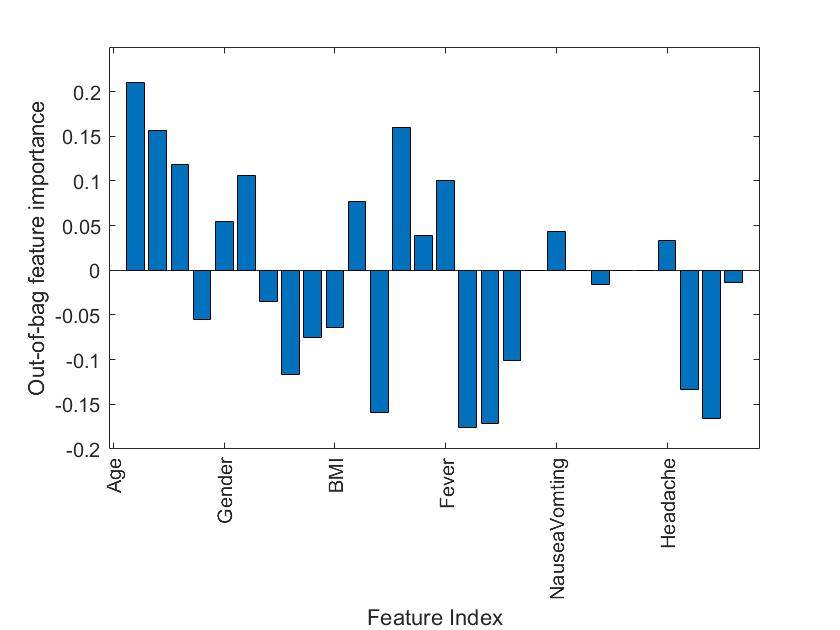

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(HCV.Properties.VariableNames(1:28))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
Ypred=categorical(Ypred); % cell array to categorical array
sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.2476

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4


Total Instance = 416
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          16                15                33                48      
    Actual_class2          18                18                21                44      
    Actual_class3          17                12                30                52      
    Actual_class4           7                13                33                39      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     16    15    33    48
    18    18    21    44
    17    12    30    52
     7    13    33    39


## Accuracy of 28.37% achieved.

### 5-fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy5_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on","CategoricalPredictors","all");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy5_(i)=sum(Ypred==Ytest1)/length(Ytest1);
    confusionmat(double(Ytest1),double(Ypred))
end

Class List in given sample
     1
     2
     3
     4


Total Instance = 155
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           9                 1                15                 7      
    Actual_class2          10                 9                 9                 6      
    Actual_class3          12                 4                 7                12      
    Actual_class4          18                10                15                11      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      9     1    15     7
    10     9     9     6
    12     4     7    12
    18    10    15    11


Class List in given sample
     1
     2
     3
     4


Total Instance = 155
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          9                  7                13                18      
    Actual_class2          1                  5                 9                14      
    Actual_class3          8                  7                10                15      
    Actual_class4          4                 10                 8                17      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      9     7    13    18
     1     5     9    14
     8     7    10    15
     4    10     8    17


Class List in given sample
     1
     2
     3
     4


Total Instance = 155
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          11                2                  6                13      
    Actual_class2          15                4                 14                10      
    Actual_class3          15                5                 11                13      
    Actual_class4          15                2                  6                13      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     11     2     6    13
    15     4    14    10
    15     5    11    13
    15     2     6    13


Class List in given sample
     1
     2
     3
     4


Total Instance = 155
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           8                3                 16                15      
    Actual_class2          12                5                 12                 8      
    Actual_class3          11                8                  9                13      
    Actual_class4          11                4                  9                11      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      8     3    16    15
    12     5    12     8
    11     8     9    13
    11     4     9    11


Class List in given sample
     1
     2
     3
     4


Total Instance = 155
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          7                  9                10                15      
    Actual_class2          7                  4                10                15      
    Actual_class3          7                 10                15                11      
    Actual_class4          5                  4                13                13      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      7     9    10    15
     7     4    10    15
     7    10    15    11
     5     4    13    13


accuracy5_

accuracy5_ =     0.2323    0.2645    0.2516    0.2129    0.2516


avg_accuracy_5=mean(accuracy5_)

avg_accuracy_5 = 0.2426

### 10-fold cross validation

fold=10;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy10_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on","CategoricalPredictors","all");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy10_(i)=sum(Ypred==Ytest1)/length(Ytest1);
    confusionmat(double(Ytest1),double(Ypred))
end

Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 1                 6                 7       
    Actual_class2          2                 0                 8                 4       
    Actual_class3          4                 3                 6                 6       
    Actual_class4          4                 1                 3                 5       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     1     6     7
     2     0     8     4
     4     3     6     6
     4     1     3     5


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 1                  6                4       
    Actual_class2          3                 0                  7                3       
    Actual_class3          3                 2                 10                3       
    Actual_class4          6                 1                  6                4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     1     6     4
     3     0     7     3
     3     2    10     3
     6     1     6     4


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          4                 1                  3                2       
    Actual_class2          6                 1                  4                2       
    Actual_class3          5                 4                 10                2       
    Actual_class4          3                 2                  6                7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      4     1     3     2
     6     1     4     2
     5     4    10     2
     3     2     6     7


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 1                 8                 8       
    Actual_class2          4                 1                 7                 6       
    Actual_class3          4                 0                 6                 2       
    Actual_class4          2                 0                 3                 8       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     1     8     8
     4     1     7     6
     4     0     6     2
     2     0     3     8


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 2                 7                 5       
    Actual_class2          3                 1                 9                 2       
    Actual_class3          3                 1                 4                 3       
    Actual_class4          3                 1                 8                 8       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     2     7     5
     3     1     9     2
     3     1     4     3
     3     1     8     8


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 4                 1                 6       
    Actual_class2          2                 2                 5                 9       
    Actual_class3          8                 0                 4                 7       
    Actual_class4          1                 0                 5                 6       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     4     1     6
     2     2     5     9
     8     0     4     7
     1     0     5     6


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          4                 0                 5                 3       
    Actual_class2          3                 0                 4                 4       
    Actual_class3          7                 3                 8                 6       
    Actual_class4          2                 1                 6                 6       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      4     0     5     3
     3     0     4     4
     7     3     8     6
     2     1     6     6


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 1                  6                2       
    Actual_class2          1                 4                  4                3       
    Actual_class3          3                 5                  3                5       
    Actual_class4          3                 1                 13                5       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     1     6     2
     1     4     4     3
     3     5     3     5
     3     1    13     5


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 3                  9                3       
    Actual_class2          2                 1                  8                1       
    Actual_class3          3                 3                  2                7       
    Actual_class4          2                 3                 10                2       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     3     9     3
     2     1     8     1
     3     3     2     7
     2     3    10     2


Class List in given sample
     1
     2
     3
     4


Total Instance = 62
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          6                 2                 7                 4       
    Actual_class2          1                 2                 7                 4       
    Actual_class3          1                 2                 6                 5       
    Actual_class4          1                 1                 6                 7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      6     2     7     4
     1     2     7     4
     1     2     6     5
     1     1     6     7


accuracy10_

accuracy10_ =     0.2097    0.2742    0.3548    0.2742    0.2419    0.2258    0.2903    0.2419    0.1290    0.3387


avg_accuracy_10=mean(accuracy10_)

avg_accuracy_10 = 0.2581

# Decision Tree on discrete data with grading

Decision_Tree=fitctree(Xtrain1,Ytrain1,'CategoricalPredictors',"all")

Decision_Tree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(Decision_Tree)


Decision tree for classification
  1  if x13=1 then node 2 elseif x13 in {2 4 5} then node 3 else 4
  2  if x28 in { 5  9 10 12 16} then node 4 elseif x28 in { 3  4  6  7  8 11 13 14 15} then node 5 else 4
  3  if x10=1 then node 6 elseif x10=2 then node 7 else 3
  4  if x1 in {3 4} then node 8 elseif x1 in {2 5 6 7} then node 9 else 2
  5  if x28 in { 4  7 14} then node 10 elseif x28 in { 3  6  8 11 13 15} then node 11 else 4
  6  if x28 in { 3  5  6  7  8 10 11 13 15 16} then node 12 elseif x28 in { 4  9 12 14} then node 13 else 3
  7  if x28 in { 3  4  7  9 10 12 13 14 15 16} then node 14 elseif x28 in { 5  6  8 11} then node 15 else 1
  8  if x11=2 then node 16 elseif x11 in {1 3} then node 17 else 4
  9  if x3 in {2 3 4} then node 18 elseif x3=5 then node 19 else 2
 10  if x1=2 then node 20 elseif x1 in {3 4 5 6 7} then node 21 else 4
 11  if x28 in { 6 13} then node 22 elseif x28 in { 3  8 11 15} then node 23 else 4
 12  if x5=1 then node 24 elseif x5=2 then node 25 else 3
 13  

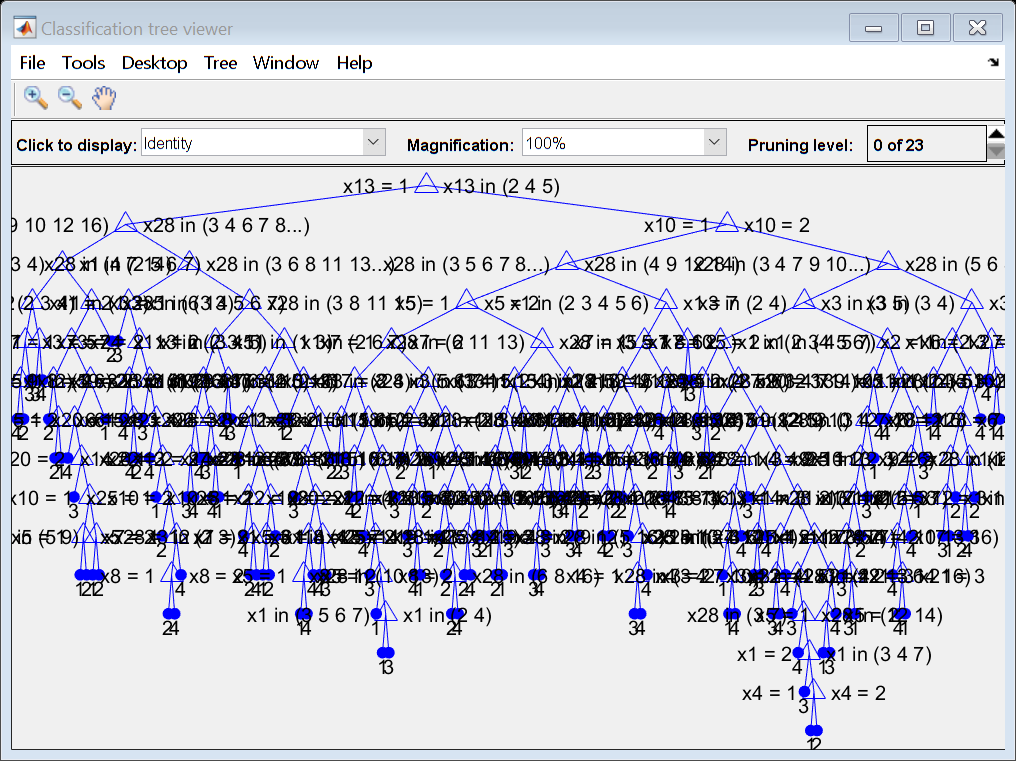

view(Decision_Tree,'mode','graph')

Ypred=predict(Decision_Tree,Xtest1); 
sum(Ypred==Ytest1)/length(Ytest1)

ans = 0.2091

20.91%

[E,SE,Nleaf,Best_prune_level]=cvloss(Decision_Tree,'subtrees','all')

E =     0.7554
    0.7492
    0.7513
    0.7492
    0.7482
    0.7513
    0.7482
    0.7451
    0.7472
    0.7420


SE =     0.0137
    0.0139
    0.0138
    0.0138
    0.0138
    0.0138
    0.0138
    0.0139
    0.0139
    0.0140


Nleaf =    157
   151
   147
   112
   108
    96
    90
    84
    64
    56


Best_prune_level = 23

prune_tree=prune(Decision_Tree,'Level',Best_prune_level)

prune_tree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(prune_tree)


Decision tree for classification
1  class = 4



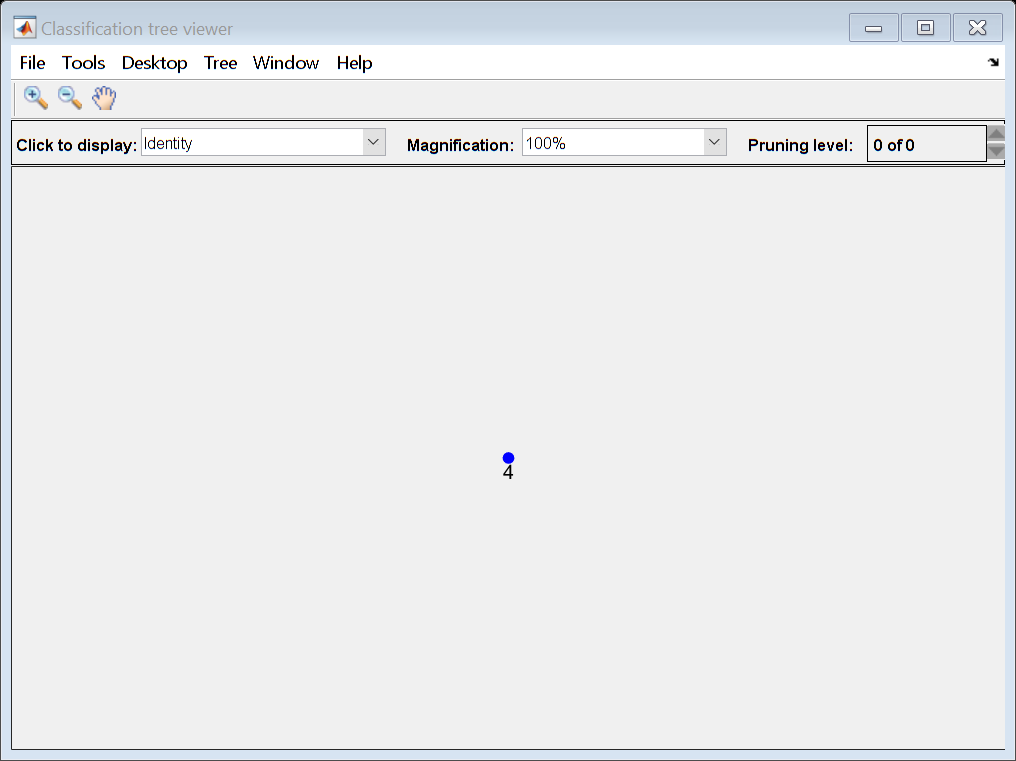

view(prune_tree,'mode','graph') % Best cross validation accuracy

Ypred=predict(prune_tree,Xtest1); 
sum(Ypred==Ytest1)/length(Ytest1)

ans = 0.2212

22.12%

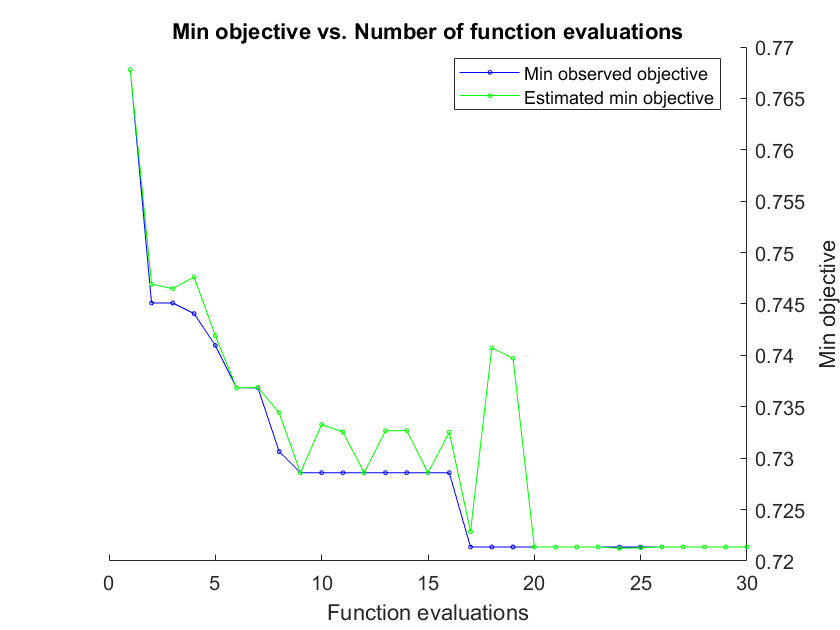

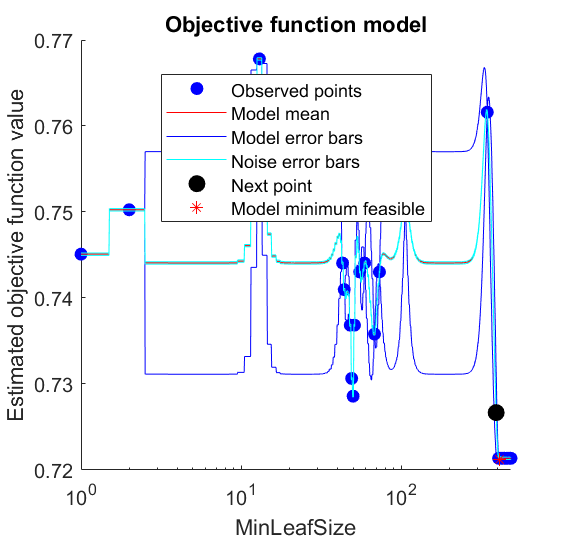

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      0.7678 |     0.12077 |      0.7678 |      0.7678 |           13 |
|    2 | Best   |      0.7451 |     0.17289 |      0.7451 |     0.74693 |            1 |
|    3 | Accept |     0.76161 |    0.087739 |      0.7451 |      0.7465 |          344 |
|    4 | Best   |     0.74407 |    0.099977 |     0.74407 |     0.74763 |           43 |
|    5 | Best   |     0.74097 |    0.098148 |     0.74097 |     0.74192 |           44 |
|    6 | Best   |     0.73684 |     0.11164 |     0.73684 |     0.73684 |           48 |
|    7 | Accept |     0.74303 |    0.083123 |     0.73684 |     0.73688 |           55 |
|    8 | Best   |    

Mdl1 =   ClassificationTree
                         ResponseName: 'Y'
                CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28]
                           ClassNames: [1    2    3    4]
                       ScoreTransform: 'none'
                      NumObservations: 969
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


Mdl1=fitctree(Xtrain1,Ytrain1,'OptimizeHyperparameters','auto','CategoricalPredictors',"all")

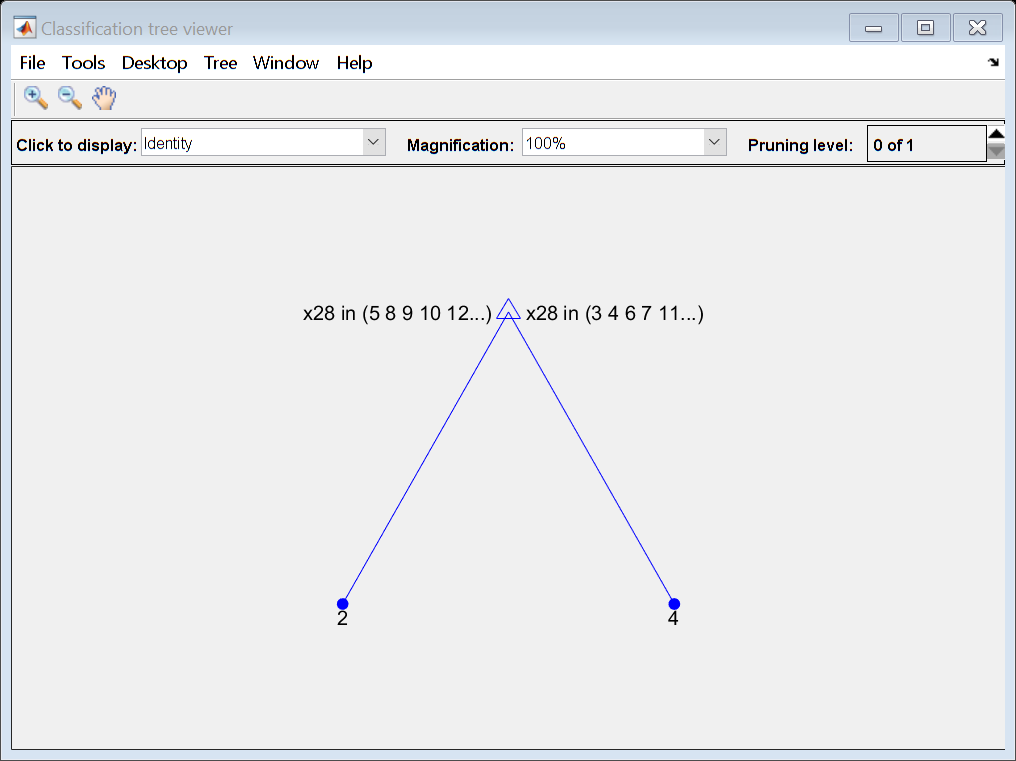

view(Mdl1,'mode','graph')

Ypred=predict(Mdl1,Xtest1); 
sum(Ypred==Ytest1)/length(Ytest1)

ans = 0.2356

23.56%

Bestobsmdl=fitctree(Xtrain1,Ytrain1,'MinLeafsize',484,"CategoricalPredictors","all")

Bestobsmdl =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


view(Bestobsmdl,'mode','graph')

Ypred=predict(Bestobsmdl,Xtest1); 
sum(Ypred==Ytest1)/length(Ytest1)

ans = 0.2356

23.56%

Bestestmdl=fitctree(Xtrain1,Ytrain1,'MinLeafsize',344,"CategoricalPredictors","all")

Bestestmdl =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28]
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


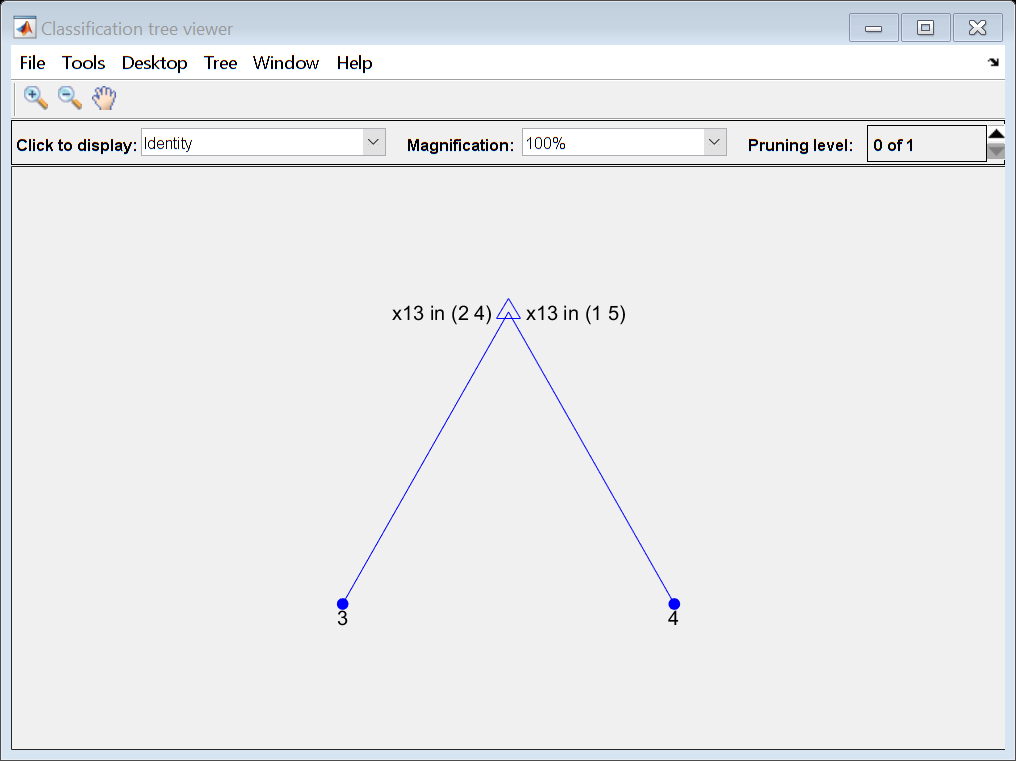

view(Bestestmdl,'mode','graph')

Ypred=predict(Bestestmdl,Xtest1); 
sum(Ypred==Ytest1)/length(Ytest1)

ans = 0.2476

24.76%

# Decision Tree on original data with grading

cdata=table2array(HCV);
x=cdata(:,1:28);
y=categorical(cdata(:,29));
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.7);

%{'Gender','Fever','NauseaVomiting','Headache','Diarrhea','Fatiguegeneralizedboneache','Jaundice','Epigastricpain','HGB','BaselinehistologicalGrading'}
%"PredictorNames",{'x2','x4','x5','x6','x7','x8','x9','x10','x28'}
Decision_Tree=fitctree(Xtrain,Ytrain,'CategoricalPredictors',[2,4:10,28])
view(Decision_Tree)
view(Decision_Tree,'mode','graph')
Ypred=predict(Decision_Tree,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

[E,SE,Nleaf,Best_prune_level]=cvloss(Decision_Tree,'subtrees','all')
prune_tree=prune(Decision_Tree,'Level',Best_prune_level)
view(prune_tree)
view(prune_tree,'mode','graph') % Best cross validation accuracy
Ypred=predict(prune_tree,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

23.32%

Mdl1=fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto','CategoricalPredictors',[2,4:10,28])
view(Mdl1,'mode','graph')
Ypred=predict(Mdl1,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

24.04%

Bestobsmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',483,"CategoricalPredictors",[2,4:10,28])
view(Bestobsmdl,'mode','graph')
Ypred=predict(Bestobsmdl,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

22.84%

Bestestmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',455,"CategoricalPredictors",[2,4:10,28])
view(Bestestmdl,'mode','graph')
Ypred=predict(Bestestmdl,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

24.04%